# Esercizi Data Model 1->4

## Esercizio 1

Stima ai minimi quadrati del valore di un resistore 

Obiettivo: stimare il valore della resistenza R0 a partire da una serie di misure ripetute di corrente e tensione

clc
clear all
close all
Esercizio = 'Esercizio N1'

Esercizio = 'Esercizio N1'

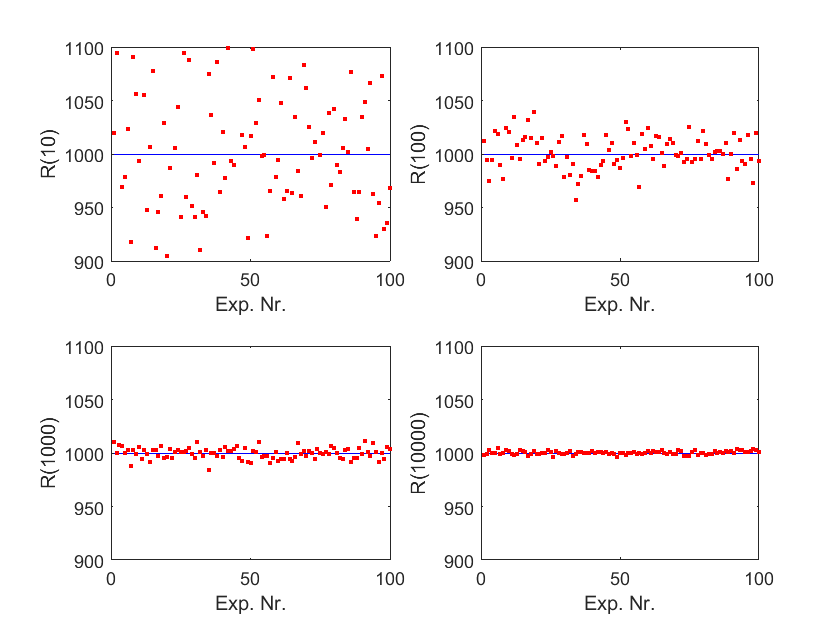

%parametri

N = [10, 100, 1000, 10000];             % Numero di misurazioni in un esperimento
i_max = 0.01;                           % A
Ro = 1000;                              % Ohm
mu = 0;                                 % Media
d = 1;                                  % Dev. standard

%Calcoliamo R stima ad ogni misura

M = 100;                                        % Numero ripetizioni dell'esperimento

for k = 1 : length(N)                           % devo ripetere l'esperimento per ogni valore di N

    for j = 1 : M

        %Corrente
        %DOMANDA SULLA DISTRIBUZIONE
        io = (2*i_max)*(rand(N(k),1)-0.5);      % Il segnale di corrente è un vettore colonna di N elementi
        i = io;                                 % superfluo ma chiarisce

        %Tensione
        uo = Ro * i;                            % Segnale tensione (noRumore)
        n = d*randn(N(k),1);                    % Rumore sulla tensione in uscita
        u = uo + n;                             % Tensione in uscita

        %Resistenza
        R(j,k) = (u'*i) / (i'*i);               % Resistenza
    end
end

% Plot
figure(1)
clf

K=[1:M]';                                       % Un vettore colonna di 100 elementi
for i = 1 : 4
    subplot(2,2,i)
    plot(K,ones(size(K))*Ro,'b',K,R(:,i),'.r')
    axis([0 M 0.9*Ro 1.1*Ro])
    if(i==1)
        xlabel('Exp. Nr.'),ylabel('R(10)')
    elseif(i==2)
        xlabel('Exp. Nr.'),ylabel('R(100)')
    elseif(i==3)
        xlabel('Exp. Nr.'),ylabel('R(1000)')
    else
        xlabel('Exp. Nr.'),ylabel('R(10000)')
    end
end

## Esercizio 2

clc 
clear all
close all
Esercizio = 'Esercizio N2'

Esercizio = 'Esercizio N2'

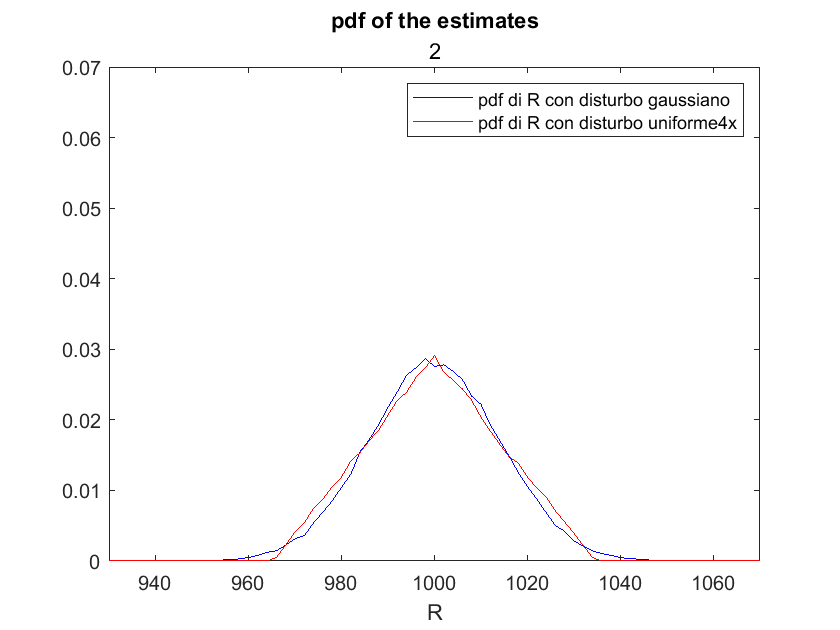

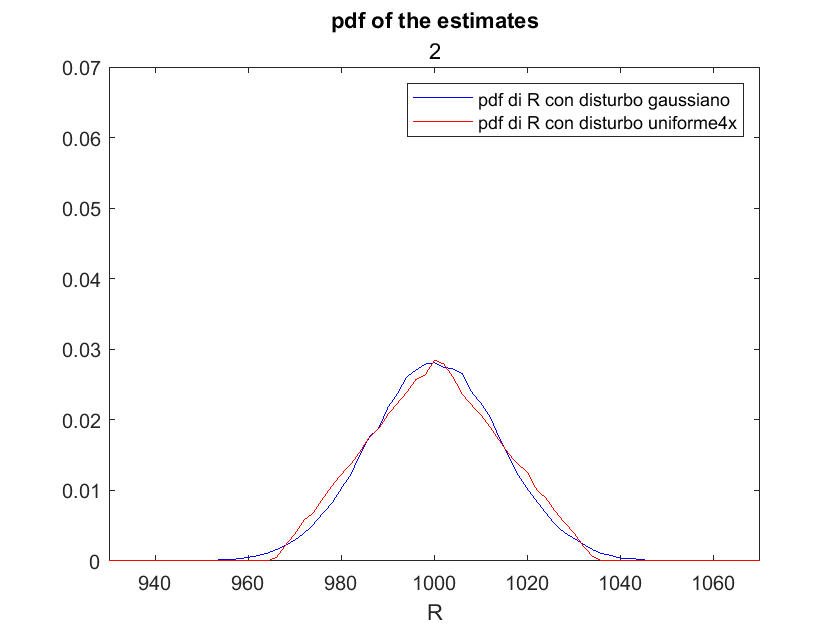

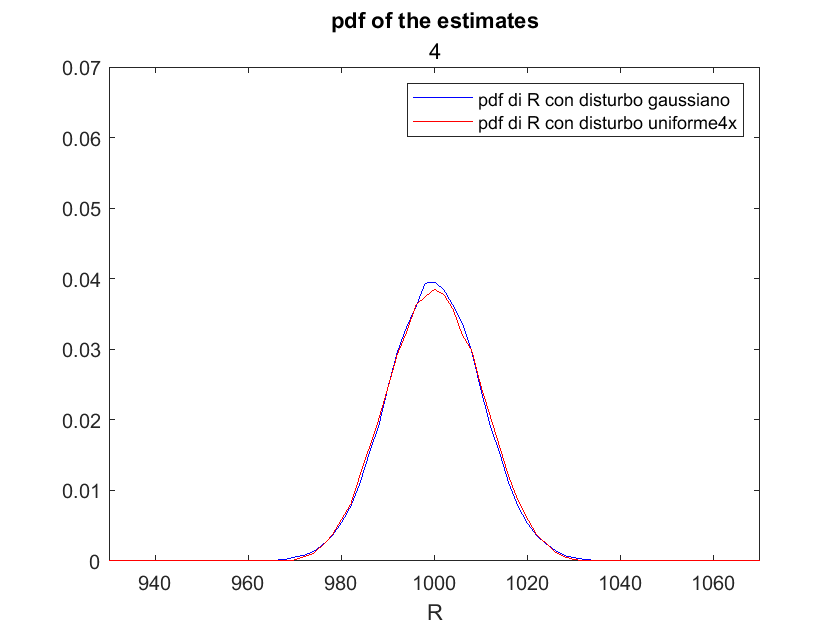

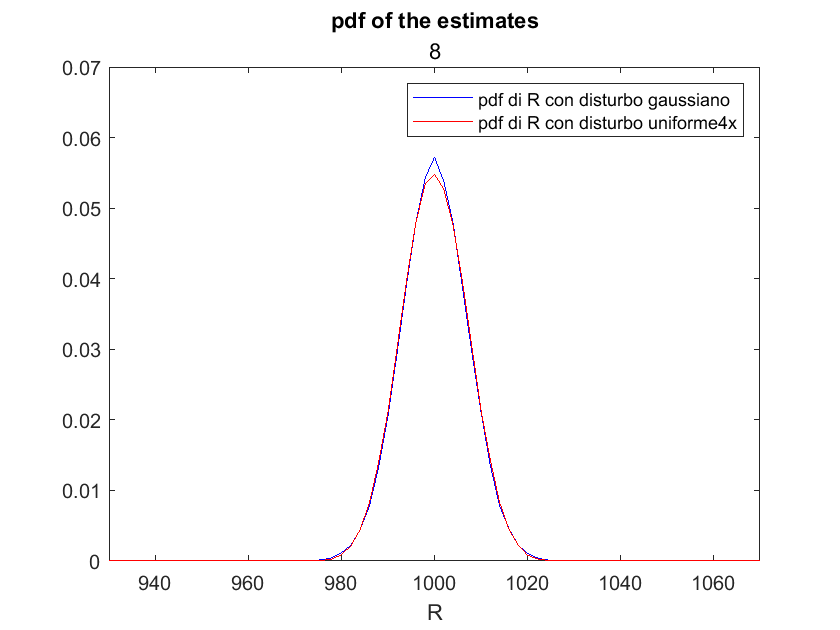


N_2 = [1, 2, 4, 8];             % Numero di misurazioni in un esperimento
io_max= 0.01;                   % A
Ro = 1000;                      % Ohm
mu = 0;                         % Media
d_2 = 0.2;                      % Dev. standard

%Calcoliamo R stimato ad ogni misura:
M_2 = 100000;                                           % Numero ripetizioni dell'esperimento

for k = 1 : length(N_2)                                 % devo ripetere l'esperimento per ogni valore di N
    
    for j = 1 : M_2

        %Corrente
        i = io_max*ones(N_2(k),1);                      % Il segnale di corrente è un vettore colonna di N elementi

        %Tensione
        uo = Ro * i;                                    % Segnale tensione (noRumore)
        n_u_2 = d_2*(2*sqrt(3))*(rand(N_2(k),1)-0.5);   % Rumore distribuzione uniforme 
        n_g_2 = d_2*randn(N_2(k),1);                    % Rumore distribuzione gaussiana
        u_u = uo + n_u_2;                               % Tensione in uscita con rumore uniforme
        u_g = uo + n_g_2;                               % Tensione in uscita con rumore gaussiano
        
        %Resistenza
        R_u(j,k) = (u_u'*i) / (i'*i);                   %Rumore con rumore uniforme
        R_g(j,k) = (u_g'*i) / (i'*i);                   %Resistenza con rumore gaussiano

    end
end

BinWidth=2;                 %Definiamo la larghezza degli istogrammi
X=[900:BinWidth:1100];

for k=1:4
    pdf_g(:,k)=hist(R_g(:,k),X)/BinWidth/M_2;    % estimated pdf
    pdf_u(:,k)=hist(R_u(:,k),X)/BinWidth/M_2;    % estimated pdf
end


% Plot
clf
for k=1:4
    %subplot(4,1,k)
    figure(k+1)
    plot(X,pdf_g(:,k),'b',X,pdf_u(:,k),'r'),title('pdf of the estimates',2^(k-1)),xlabel('R'), legend('pdf di R con disturbo gaussiano', 'pdf di R con disturbo uniforme4x')
    axis([930 1070 0 0.07])
  
end

%Indipendentemente dal tipo di rumore, per N->inf, la distribuzione tende a
%alla Gaussiana


## Esercizio 3

clc 
clear all
close all
Esercizio = 'Esercizio N3'

Esercizio = 'Esercizio N3'

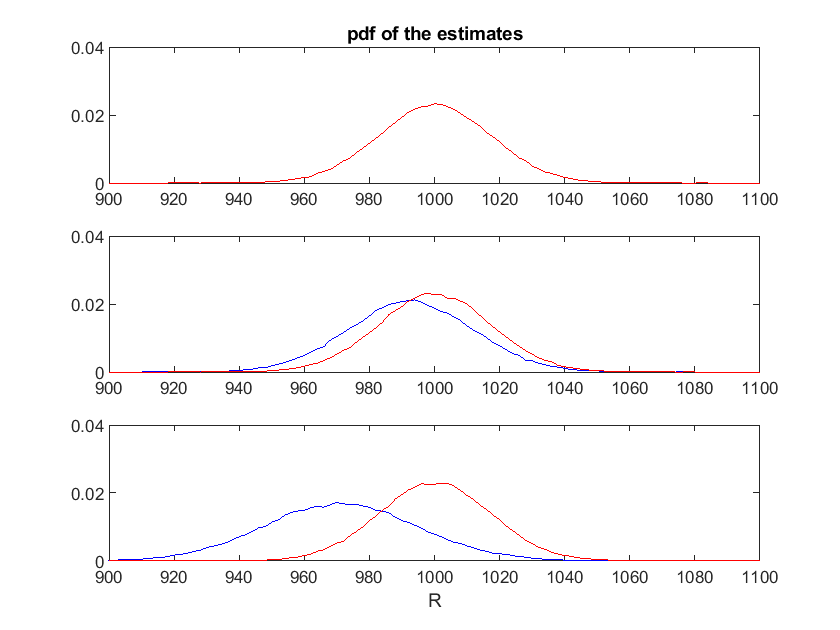

%In questo esercizio devo riportare le misure raccolte nelle unità di misura
%di riferimento: la corrente quindi data in mA, va riportata in A.

N_3 = 100;                      % Numero di misurazioni in un esperimento
i_max= 0.01;                    % 0.01A = 10mA
Ro = 1000;                      % Ohm
mu = 0;                         % Media
d_3 = 1;                        % Dev. standard

%Calcoliamo R stima ad ogni misura
M_2 = 100000; %M_2 = M_3                            % Numero ripetizioni dell'esperimento

for k = 1 : 3                                       % devo eseguire 3 volte, una per ogni deviazione standard, dev=[0 0 .5 1]
   
    for j = 1 : M_2
        
        %Corrente
        io = (2*i_max)*(rand(N_3,1)-0.5);           % Il segnale di corrente è un vettore colonna di N elementi (dim 100x1)   
        ni = (((k-1)/2)*(1/1000)*randn(size(i)));   % Il primo rumore (distribuzione normale) avrà dev1=0, il secondo dev2 = 0.5, il terzo dev3=1
        i = io + ni;                                % La corrente è data come somma del segnale piu il rumore

        %Tensione
        uo = Ro * io;
        n_g_3 = d_3*randn(size(i));                 % Rumore distribuzione gaussiana
        u_g = uo + n_g_3;                           % Tensione in uscita 
        
        %Resistenza
        R0(j,k) = (u_g'*io) / (io'*io);             % Resistenza con corrente senza rumore
        R1(j,k) = (u_g'*i) / (i'*i);                % Resistenza concorrente con rumore a dev variabile [0 0.5 1]

    end
end


BinWidth=2;
X=[0:BinWidth:1100];

for k=1:3
    pdf_0(:,k)=hist(R0(:,k),X)/BinWidth/M_2;    % estimated pdf
    pdf_1(:,k)=hist(R1(:,k),X)/BinWidth/M_2;    % estimated pdf
end

%Plot
figure(3)
clf

for k=1:3

    subplot(3,1,k)
    plot(X,pdf_1(:,k),'b',X,pdf_0(:,k),'r')
    axis([900 1100 0 0.04])
    
end
subplot(3,1,1),title('pdf of the estimates')
subplot(3,1,3),xlabel('R')


%DOMANDE:


## Esercizio 4

L'importanza della scelta della variabile indipendente o dell'input

Nel precedente esercizio si è evidenziato che il rumore sull'input or sulla variabile indipendente crea **un bias**, ovvero **un errore sistematico** o una tendenza che influisce **sui risultati di un esperimento**.

clc                             % Pulizia Command Window             
clear all                       % Pulizia Variabili Workspace
close all                       % Chiusura delle finestre
Esercizio = 'Esercizio N4'      % Questa stringa serve solo per una questione di ordine

Esercizio = 'Esercizio N4'

In questo esercizio si farà riferimento alle stesse variabili richiamate anche negli esercizi precedenti, per evitare confusioni, si è voluto aggiungere una desinenza : `4`

N_4 = 100;                      % Numero di misurazioni in un esperimento
io_4= 0.01;                     % A 
Ro = 1000;                      % Ohm
mu = 0;                         % Media
d_4 = 1;                        % Dev. standard

%Calcoliamo R stima ad ogni misura
M_2 = 100000;  %M_4 = M_2                           % Numero ripetizioni dell'esperimento

for k = 1 : length(N_4)                             % devo ripetere l'esperimento per ogni valore di N

    for j = 1 : M_2

        i = io_4*2*(rand(N_4(k),1)-0.5);            % Viene generata una corrente "i", con ampiezza pari a io_4.
                                                    % Il segnale di corrente è un vettore colonna di N elementi
        
        uo = Ro * i;                                % Viene calcolata la tensione mediante la prima legge di Ohm
        n_g_4 = mu + d_4*randn(N_4(k),1);           % Rumore distribuzione gaussiana
        u_g = uo + n_g_4;                           % Tensione in uscita: è la somma tra il rumore gaussiano 
                                                    % n_g_4 alla tensione di uscita ideale uo.

% Successivamente, vengono calcolate tre stime della resistenza, mediante metodo dei minimi quadrati: 
% R_4_a (resistenza diretta), G_4 (conduttanza) e R_4_b (resistenza indiretta).

        R_4_a(j,k) = (u_g'*i) / (i'*i);             % Resistenza diretta
        G_4(j,k) = (u_g'*i) / (u_g'*u_g);           % Conduttanza
        R_4_b(j,k) = 1/(G_4(j,k));                  % Resistenza indiretta

    end
end


### **Il metodo dei minimi quadrati** 

Il metodo dei minimi quadrati è **una tecnica utilizzata per stimare i parametri di un modello matematico in modo che la somma dei quadrati degli errori tra i dati osservati e i valori predetti dal modello sia minimizzata.** In pratica, cerca di trovare i valori dei parametri che forniscono la migliore approssimazione ai dati sperimentali.

Nel contesto dell'esempio fornito, l'obiettivo è stimare la Resistenza diretta e la Conduttanza. Il modello utilizzato è la relazione tra la tensione (`u_g`) e la corrente (`i`). Il metodo dei minimi quadrati viene utilizzato per **trovare i valori di resistenza e conduttanza che minimizzano la differenza tra i dati sperimentali e il modello**.

Per comprendere come si arriva a questa formula R_4_a(j, k) = (u_g' * i) / (i' * i) , dobbiamo considerare il modello lineare che stiamo utilizzando per approssimare la relazione  tra la tensione (`u_g`) e la corrente (`i`) attraverso la resistenza (`R`).

Il calcolo della resistenza diretta tramite il metodo dei minimi quadrati avviene nel seguente modo:

- Considerando un vettore `u_g` delle tensioni misurate e un vettore `i` delle correnti misurate, possiamo scrivere **l'equazione del modello** come una **forma matriciale**:  

**u_g = X * R + noise ** 

              dove `X` è una matrice che ha come colonne i vettori `i`

- **L'obiettivo del metodo dei minimi quadrati è trovare il vettore **`R`** che minimizza la quantità:** 

**||u_g - X * R||^2**  = (u_g - X * R)' * (u_g - X * R)

             dove `||.||` indica la norma Euclidea.

- La soluzione ottimale può essere trovata impostando la derivata parziale rispetto a `R` uguale a zero:

**2 * X' * (u_g - X * R) = 0**

- Risolvendo questa equazione per `R`, otteniamo la seguente formula:

**R = (X' * X)^-1 * X' * u_g**

Considerando `X` come una matrice che contiene solo il vettore `i`, la formula diventa la nota:** R_4_a(j, k) = (u_g' * i) / (i' * i)**

Il calcolo della conduttanza tramite il metodo dei minimi quadrati avviene in modo analogo, utilizzando il vettore delle tensioni misurate `u_g` e il vettore delle correnti misurate `i`. L'obiettivo è trovare il valore di conduttanza che minimizza la differenza tra i dati sperimentali `u_g` e il modello predetto `i * G`, dove `G` è la conduttanza da stimare. Il processo di calcolo e minimizzazione della somma dei quadrati degli errori è simile a quanto descritto per la resistenza diretta.

In entrambi i casi, **il metodo dei minimi quadrati permette di ottenere le stime dei parametri che forniscono la migliore approssimazione ai dati sperimentali**, tenendo conto delle discrepanze tra i dati e il modello. Questa tecnica è ampiamente utilizzata nell'analisi dei dati per stimare i parametri di un modello e ottenere risultati più accurati e rappresentativi.

% Viene creato un istogramma dei dati stimati per la resistenza diretta (R_4_a) e la resistenza indiretta (R_4_b)
BinWidth=2;                                             % Larghezza di bin dell'Istogramma
X=[0:BinWidth:1100];                                  % Rappresenta gli estremi dei bin dell'istogramma, con 
                                                        % valori compresi tra 900 e 1100 con passo BinWidth di 2.
                                                        % Una finestre di -10% di R


Vengono calcolate le stime delle densità di probabilità (PDF):

**Una stima delle densità di probabilità** (PDF, Probability Density Function)** è una funzione che approssima la **

**distribuzione di probabilità di una variabile casuale continua.** La PDF rappresenta la probabilità che una 

variabile casuale cada in un certo intervallo di valori.

Queste stime vengono ottenute **dividendo l'istogramma dei dati per la larghezza di bin (BinWidth) così da**

**mostrare la Frequenza Relativa** e **per il numero totale di ripetizioni dell'esperimento (M_2), al fine di **

**ottenere una stima normalizzata** della PDF, Senza normalizzazione, il numero di occorrenze in ciascun bin 

è direttamente proporzionale al numero di ripetizioni dell'esperimento, quindi i valori sarebbero diversi 

da un esperimento all'altro.

    pdf_4_a(:,1)=hist(R_4_a(:,1),X)/BinWidth/M_2;    % estimated pdf Resistenza diretta
    pdf_4_b(:,1)=hist(R_4_b(:,1),X)/BinWidth/M_2;    % estimated pdf Resistenza indiretta

% Plot

figure(2)
clf
k=1

k = 1

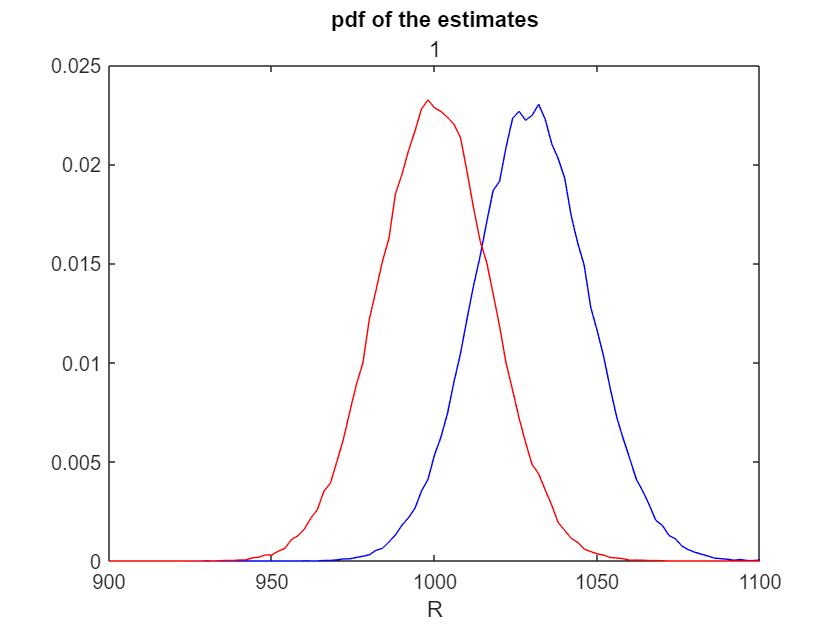


% Stime delle PDF per la resistenza indiretta in Blu e per la resistenza diretta in Rosso
plot(X,pdf_4_b(:,k),'b',X,pdf_4_a(:,k),'r'),title('pdf of the estimates',2^(k-1)),xlabel('R')
axis([900 1100 0 0.025])

   
    % sull'asse x i valori di resistenza (R) nel range specificato da 940 a 1060 
    % sull'asse y la densità di probabilità corrispondente


Ogni voltsa che viene applicato **un rumore sulla variabile in input, verrà osservato un comportamento direzionale anomalo, ovvero un bias**, un errore sistematico. A meno che non venga utilizzato un metodo appositamente realizzato. In questo caso **la presenza al denominatore di una variabile: la tensione, disturbata dal rumore, definisce la presenza di un bias visibile.** Infatti i**l valore della resistenza valutata in maniera indiretta, presenta un errore sistematico a causa del rumore presente sulla tensione**. Dato che nella formula per il calcolo della Resistenza Diretta, è la corrente (privsa di rumore) ad essere elevata al quadrato al denominatore, il bias non è visibile. 

Questo fa capire che **il segnale con il più alto valore di Rapporto Segnale-Rumore (SNR), dovrebbe essere utilizzato come una variabile indipendente o un input**, in modo da ridurre l'effetto del bias, poiché da quanto appena dimostrato, il bias risulta proporzionale all'inverso del SNR.

In conclusione: L'utilizzo di un segnale con un rapporto segnale-rumore (SNR) più elevato come variabile indipendente o input può offrire alcuni vantaggi nell'ambito delle misurazioni e delle stime. Un SNR più elevato implica che il segnale di interesse sia più forte rispetto al rumore di fondo. Ciò può facilitare l'identificazione e l'estrazione del segnale desiderato dai dati misurati. In altre parole, un segnale più forte rispetto al rumore può migliorare la precisione delle misure e ridurre l'incertezza associata all'effetto del rumore.